close all;
w_filter_1 = cfirpm(N_TX-1,[f_grid(1),f_grid(N_grid/2),f_grid(N_grid/2+1),f_grid(end)],[1,1,0,0]);
norm(w_filter_1)

ans = 0.6941

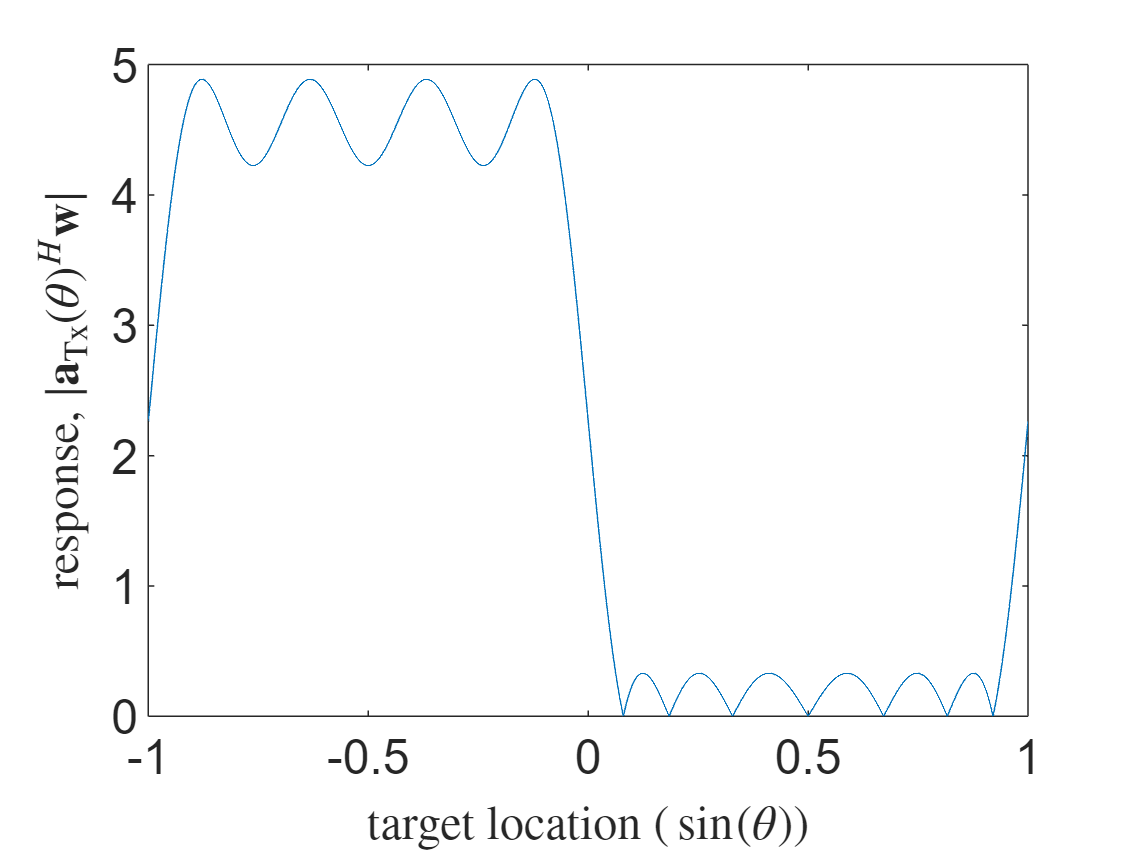

w_filter_1 = w_filter_1.'*(sqrt(PT)/norm(w_filter_1));
% w_filter_2 = cfirpm(N_TX-1,[f_grid(1),0,0.1,f_grid(end)],[1,1,0,0]);
plot(f_fine, abs(A_TX_fine'*w_filter_1))
hold on
% plot(f_fine, abs(A_TX_fine'*w_filter_2'))
xlabel('target location ($\sin(\theta)$)','interpreter','latex')
ylabel('response, $|\mathbf{a}_{\rm Tx}(\theta)^H\mathbf{w}|$','interpreter','latex')
fontsize(gca,16,"points")

narrower beams

% close all;
w_filter_1 = cfirpm(N_TX-1,[f_grid(1), f_grid(2), f_grid(3),f_grid(end)],[1,1,0,0]);% f_grid(end)
norm(w_filter_1)

ans = 0.3287

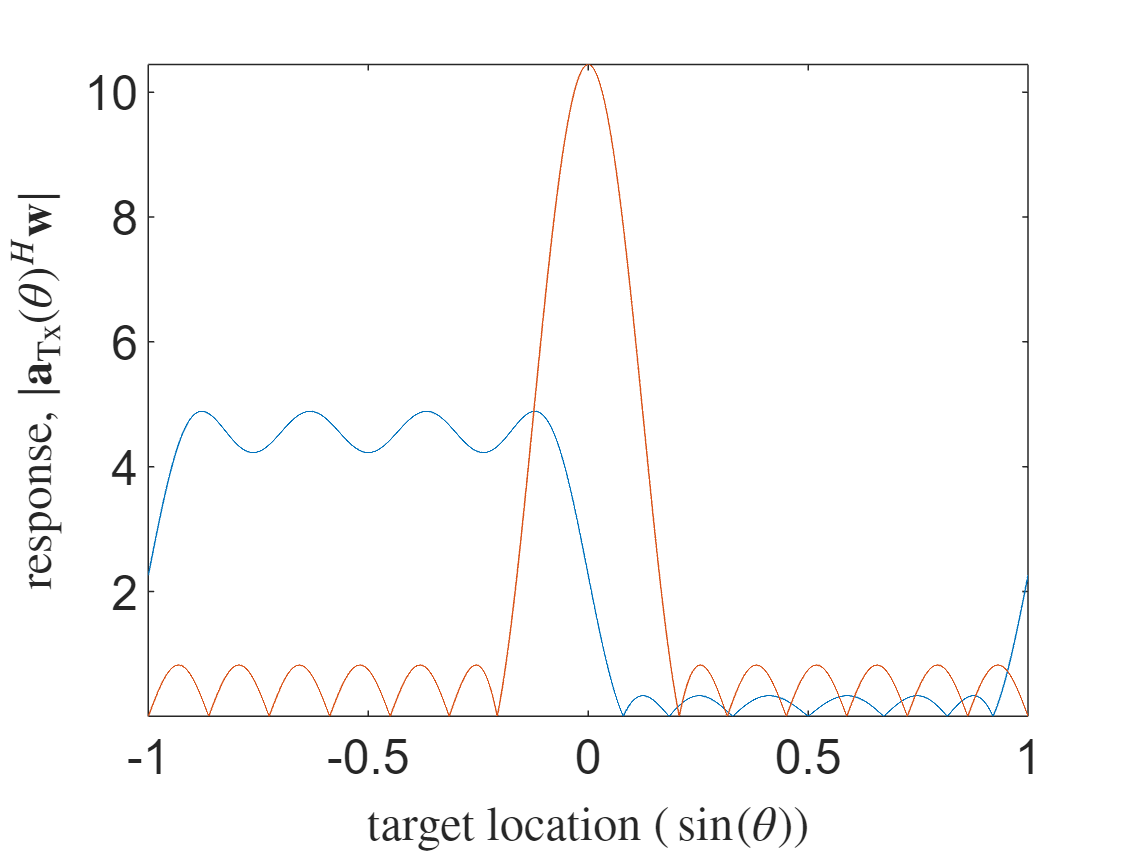

w_filter_1 = w_filter_1.'*(sqrt(PT)/norm(w_filter_1));
% w_filter_2 = cfirpm(N_TX-1,[f_grid(1),0,0.1,f_grid(end)],[1,1,0,0]);
w_filter_1 = w_filter_1.*exp(1j*pi*loc_tx'*(f_grid(1 + (8-1))-f_grid(1)));
plot(f_fine, abs(A_TX_fine'*w_filter_1))

% hold on